# **PWM - Phase-Shifted Asymmetric PWM**

This example demonstrates the use of the PWM Generation v5 driver block. The model is set up to generate three interleaved PWM signals with a frequency of 20 kHz. The pulse pattern is asymmetric.  A trigger pulse is generated for each signal right at the center of each pulse.

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file that supports **3x PWM channels including A, B and at least one Trigger output**

- Connector cable from the I/O module to the terminal board

- Terminal board

- An oscilloscope to measure the generated PWM signals

### Test Setup

In this example, PWM pulses are emitted from three PWM Generation v5 channels. You can connect an oscilloscope to the output pins on the terminal board and measure the pulses. The exact pins depend on your specific configuration file (bitstream). In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board.

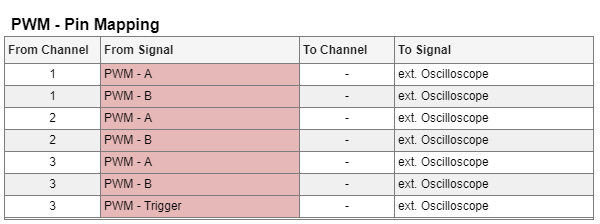

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_PWM_Asymmetric';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

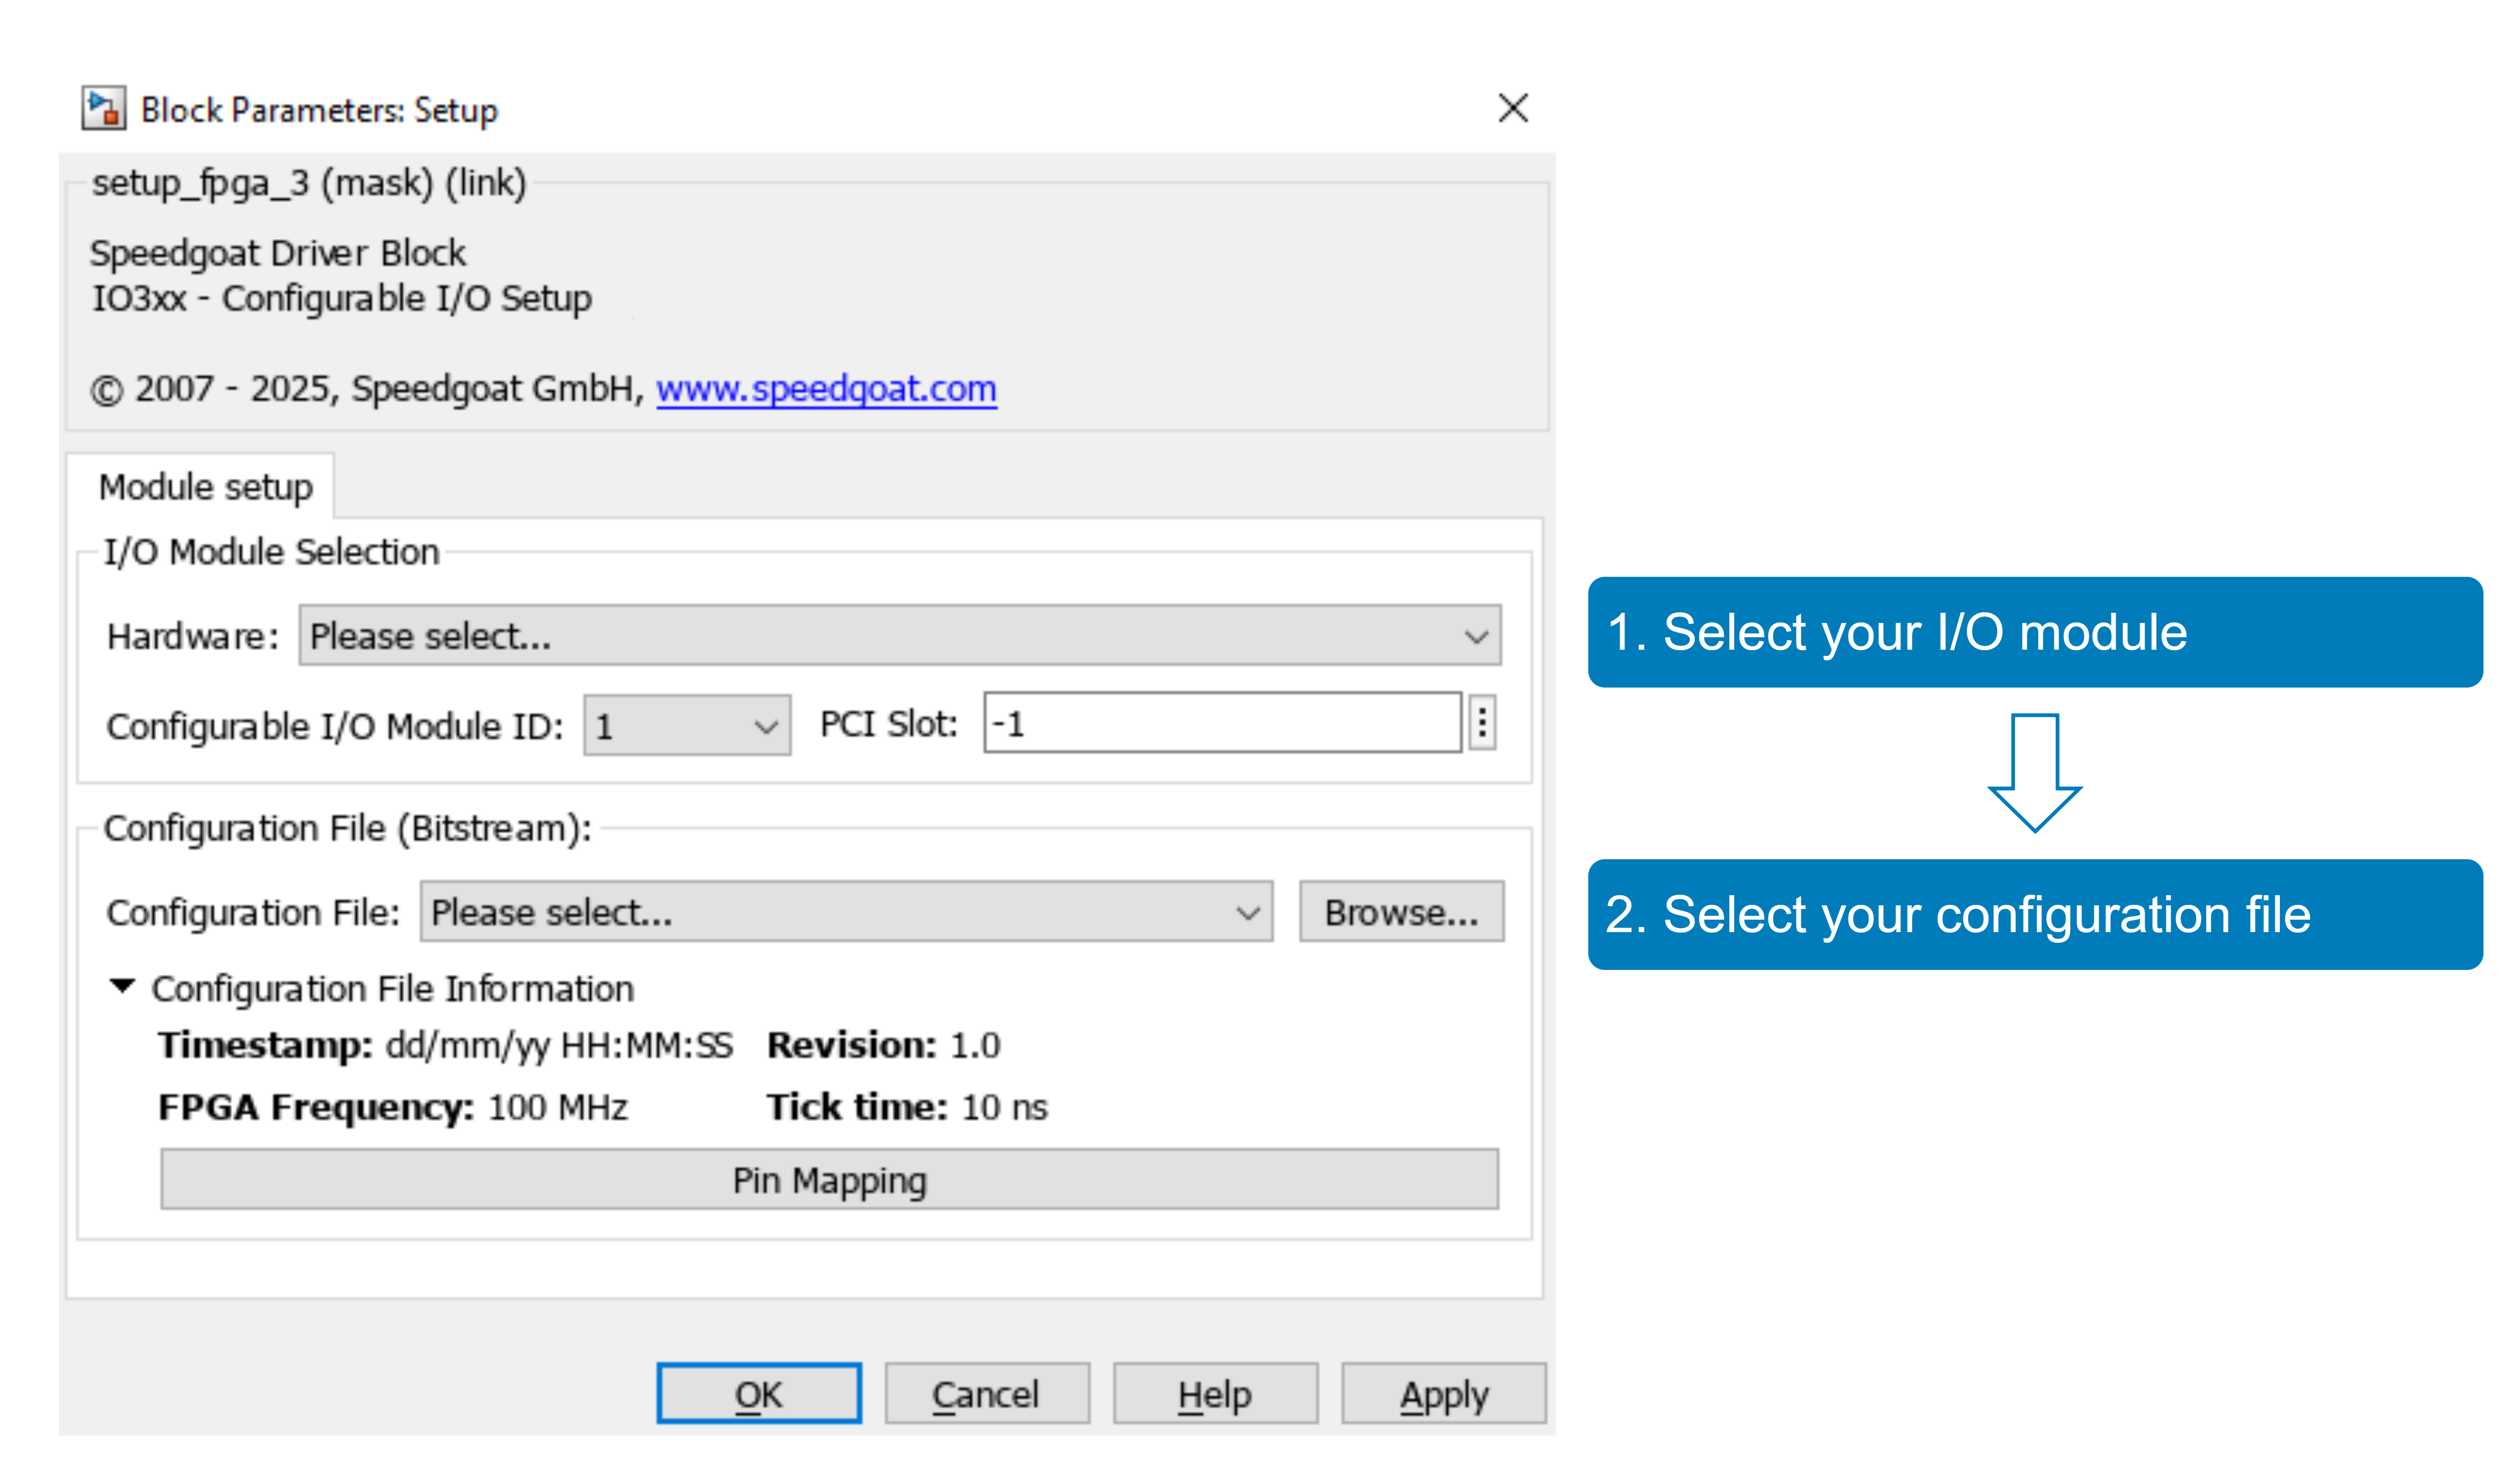

With the **Pin Mapping** button you can now check where the functionalities are located.

This model uses a sample time of 50 us. The PWM frequency is 20 kHz. The dead band is 1 us.

% specify sample times and deadband
Ts = 50e-6;
Tpwm = 50e-6;
Deadband = 1e-6;

## Model Description 

### PWM Generation

The model contains one instance of the PWM Generation v5 block. The block is assigned to PWM channels 1 to 3 (**Channel Vector** parameter) and is configured to generate three pairs of complementary PWM signals (A and B). All three PWM signals are synchronized. The same period length is defined in the block mask (**Initial Period Vector**) and all three channels are assigned by the same driver block instance. Note that different PWM channels assigned by different instances of the PWM Generation v5 driver block are not synchronized. A **PWM Phase Vector** is defined to obtain three interleaved PWM signals. The phase shift between two channels is a third of the PWM period length. The phase vector parameter results in shifted carriers.

- **PWM Phase Vector [s]:** [0 50e-6*1/3 50e-6*2/3]

- **Initial Period Vector [s]:** 50e-6

An asymmetric PWM pattern is selected. Refer to the [PWM Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_pwm_usage_notes#refsect_pwm_trigger_output) for more information about this topic. The duty cycle of output B is the complement of output A. The protection unit within the PWM module forces output B to be low when output A is high in order to prevent A and B being high at the same time. This option is important if the duty cycles of signals A and B are altered separately. The dead band is set to 1 us.

- **PWM Pattern is:** Asymmetric - On and Off are freely configurable

- **PWM B Output is:** The complement of PWM A output

- **AB-Output Protection:** B is forced off when A is on

- **Deadband Duration Vector [s]**: 1e-6 

The comparator inputs of the PWM unit are updated right at the start of each new period.

- **Update PWM Generation:** At period start

No trigger pulse is configured in the **Triggering** tab. However, the C input is activated in the **Input Ports Configuration** tab. The C signal uses the same output pin as the trigger signal. Both signals are connected with an OR gate within the module. 

The block has four active inputs with the applied settings. The rising and falling edges of the A and B signals are defined by the **A-On / B-Off** and **A-Off / B-On** inputs. The rising and falling edges of the C signal can be defined separately through the **C-On** and **C-Off** input ports.

The PWM period is constant and equal to the defined **Initial Period Vector [s]** because the **Show Period Input Port** option is disabled (in the **Input Ports Configuration **tab). 

The PWM unit on the FPGA is only enabled when the model execution starts on the real-time system. The output states before model start and after model stop are defined in the **Offline State** tab:

- **PWM Output A is:** Low when PWM generation is stopped

- **PWM Output B is:** Low when PWM generation is stopped

It is important to define the pull resistor settings in the mask of the IO3xx Setup block to obtain well defined I/O line states at model start and stop. The settings are located in the **Pull Resistor** tab.

### Input Signals

The A-On / B-Off input is set to constant 0. This leads to the rising edge of the signal right at period start. The A-Off input signal is a saw tooth which results in a varying pulse length between 10 % and 90 % of the period. The input signals for the C signal are such that a pulse is generated right at the middle of each pulse. The duration of the C pulse is 1 us.

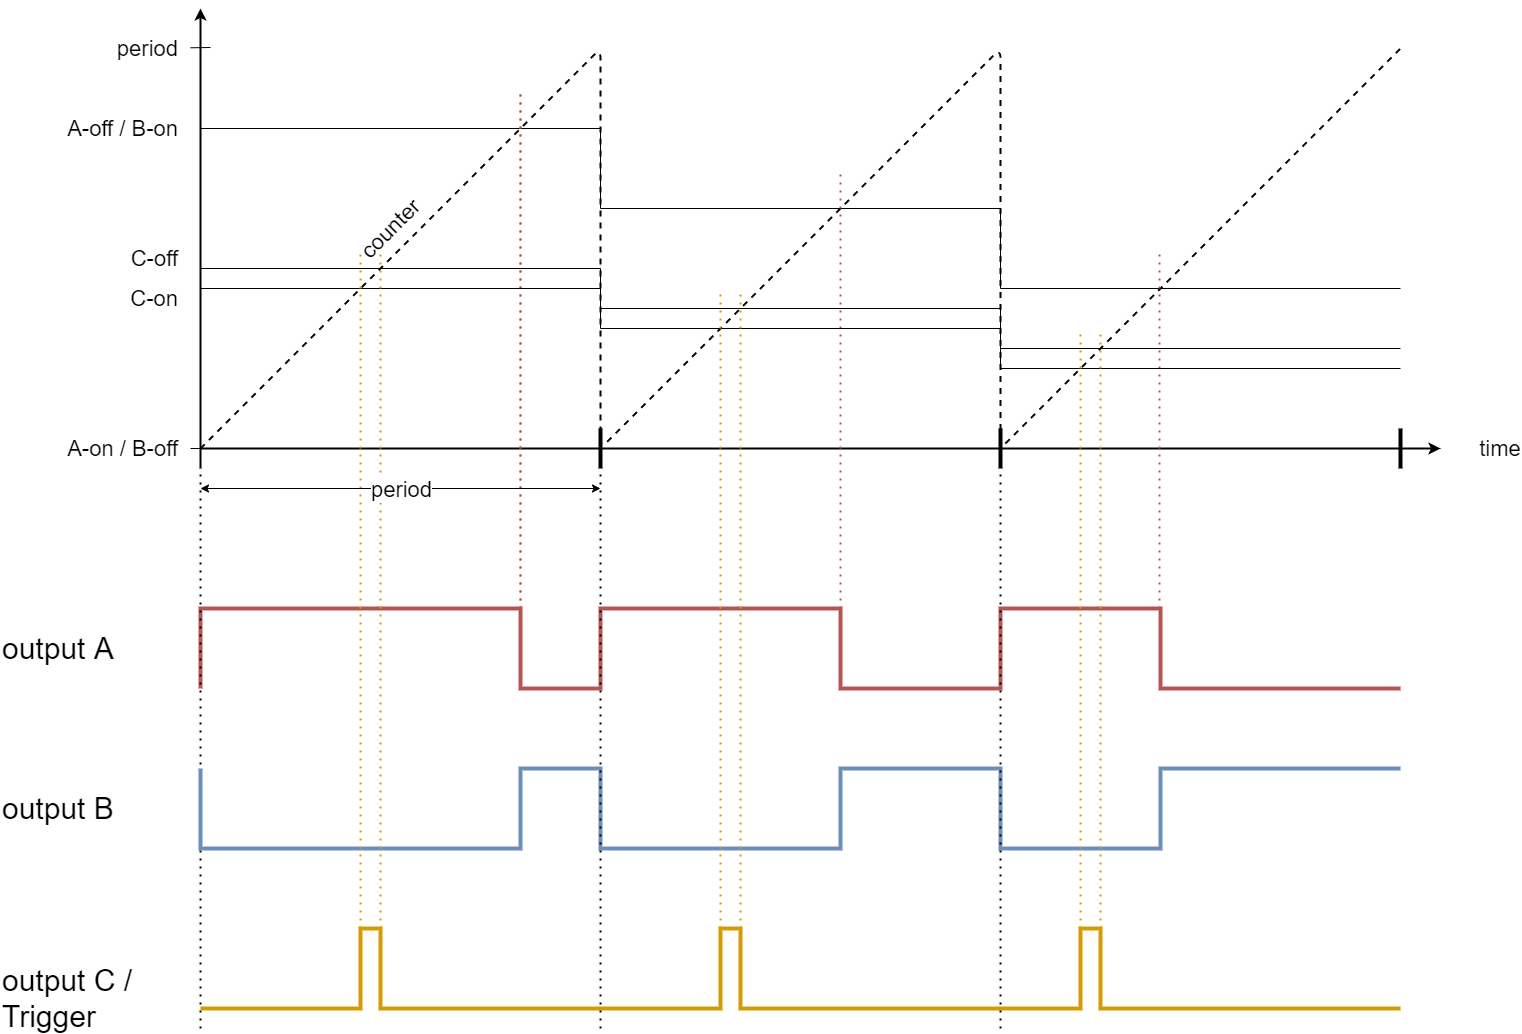

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;


### Check the Results

Run the model and connect an oscilloscope to the PWM output pins on the terminal board according to the pin mapping of your configuration file. The following figure shows signal A of the three PWM channels measured with an oscilloscope (blue: channel 1, red: channel 2 and green: channel 3). The duty cycle at the time of the measurement is about 0.18. The three signals are synchronous with a phase shift of a third of the period length. The fourth probe measures output C of PWM channel 3 (yellow). The 1 us pulse appears right at the center of pulse A (green).

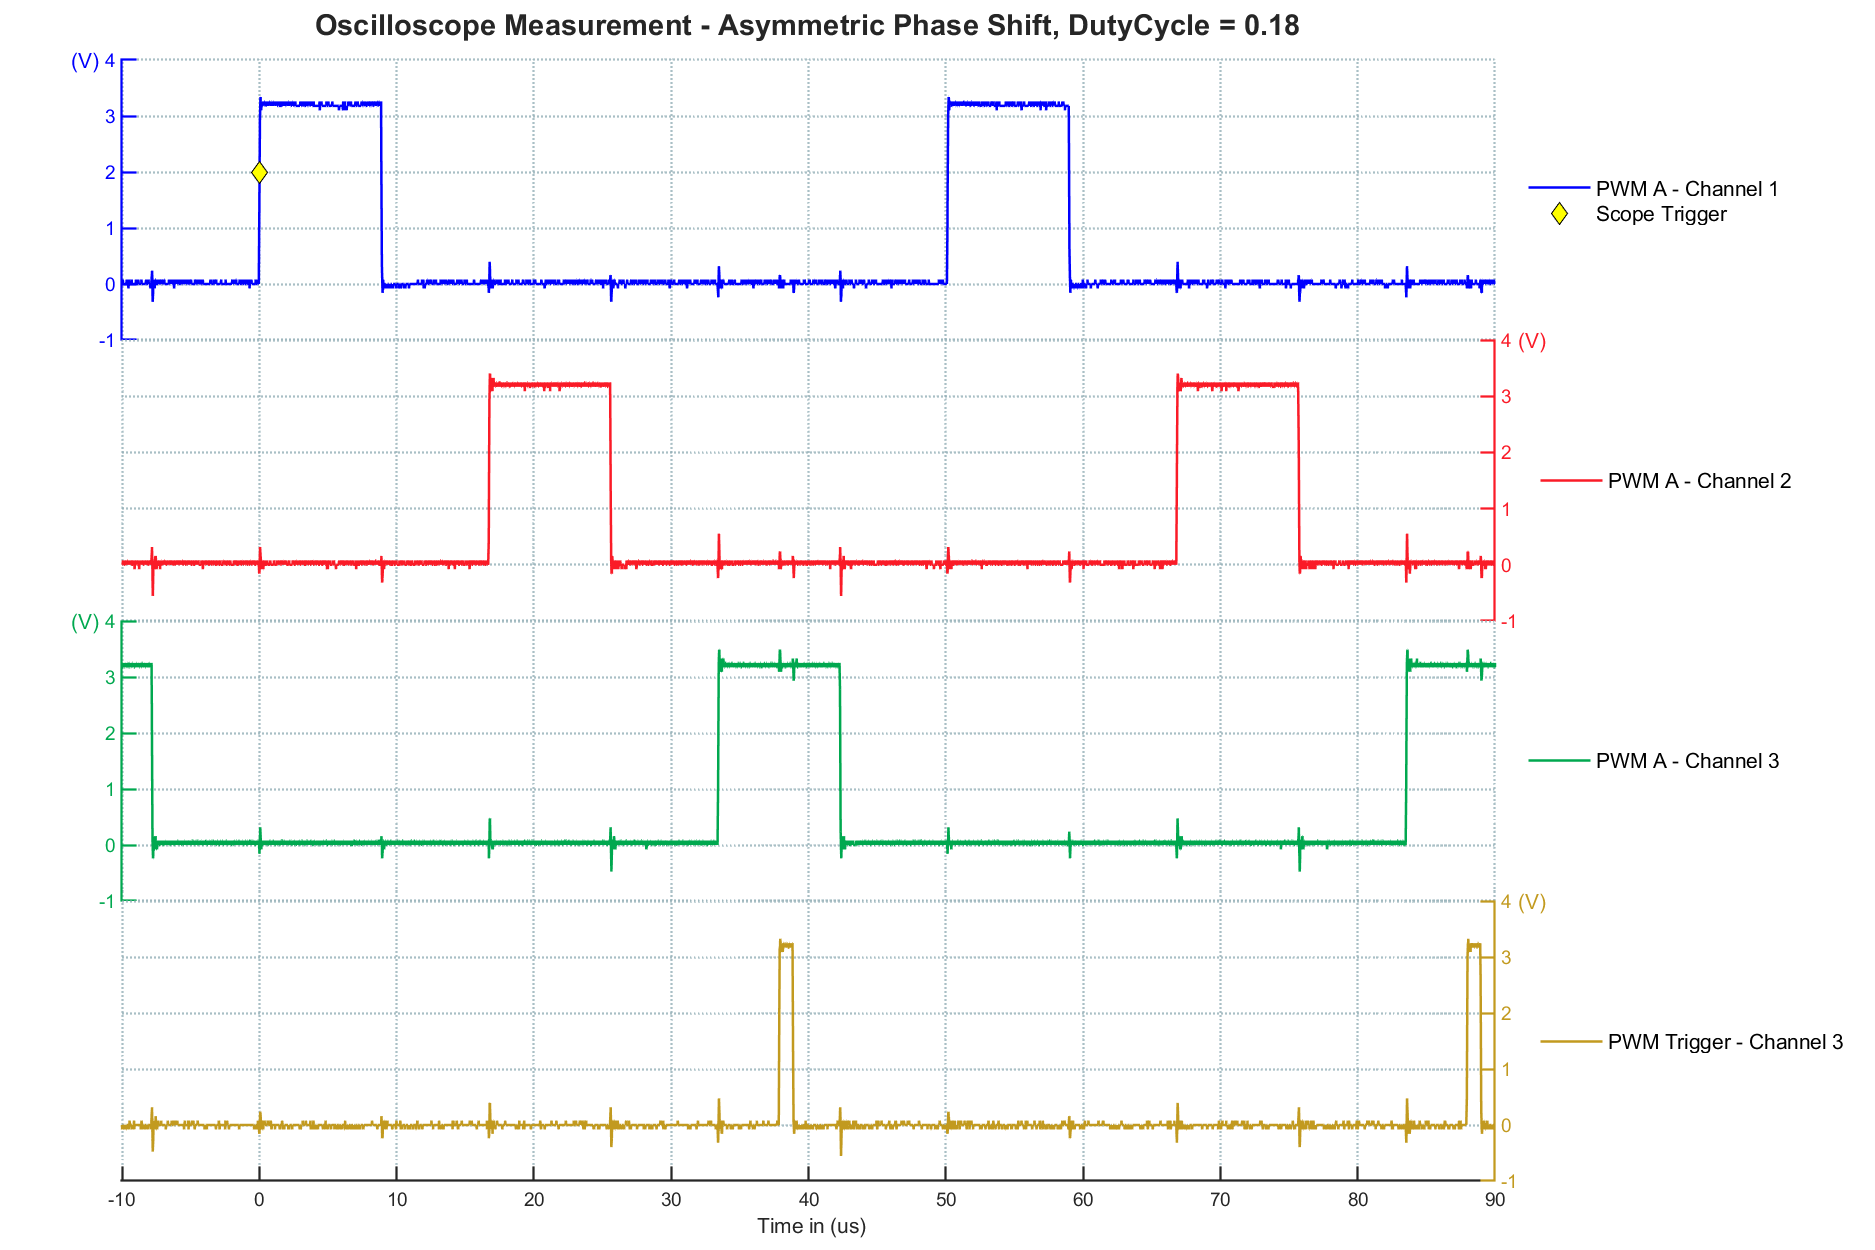

The second graph shows the same signals. The duty cycle at the time of the second measurement is about 0.9. The 1 us pulse of output C of channel 3 (yellow) appears right at the center of pulse A of channel 3 (green).

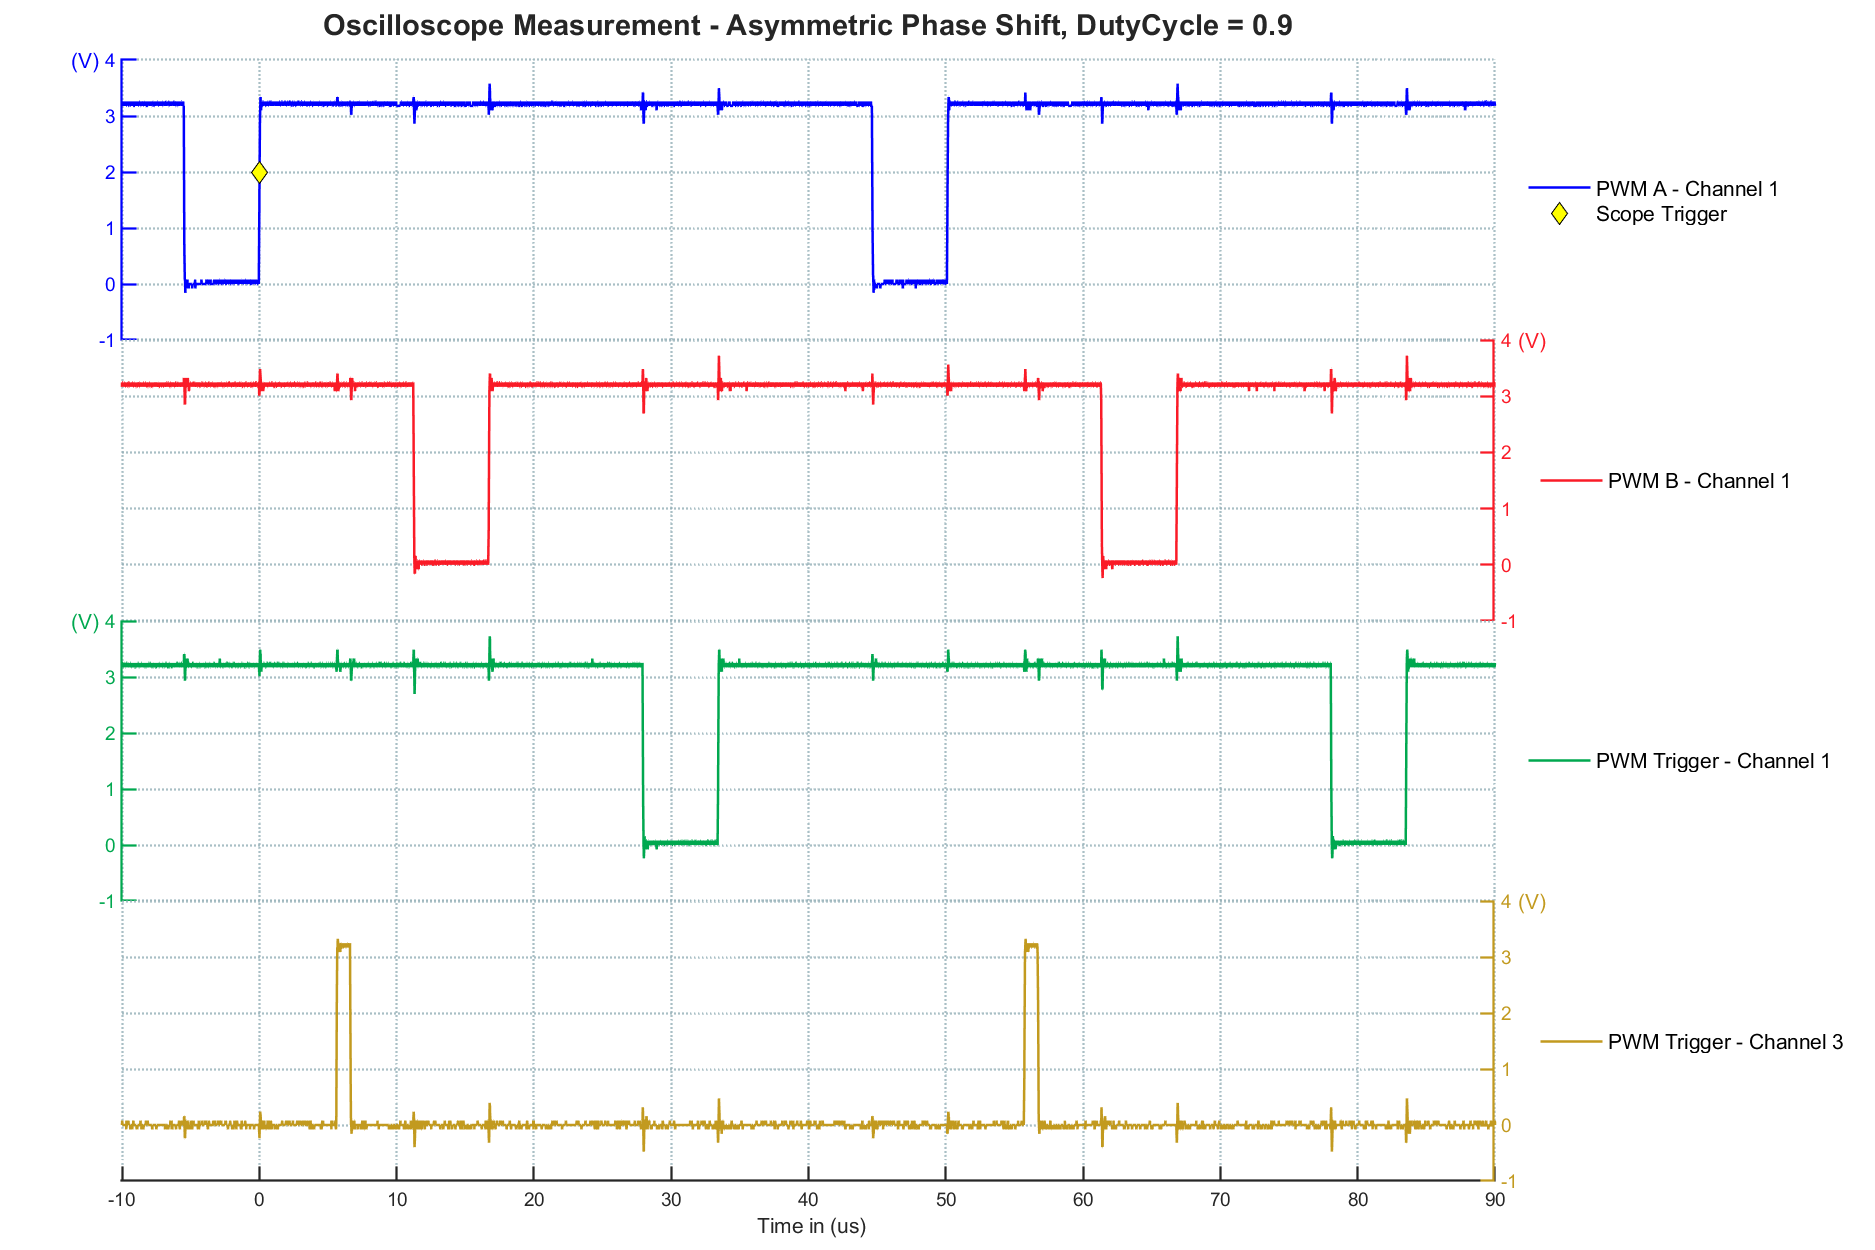

## Additional References

- [PWM documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_pwm)